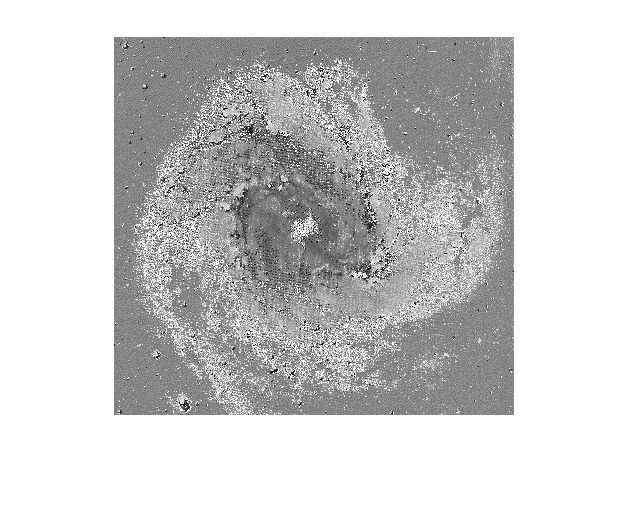

%ques. 7 histogram equlization of an image
A=imread('C:\Users\tvasu\Downloads\m83.tif');
figure,imshow(A);

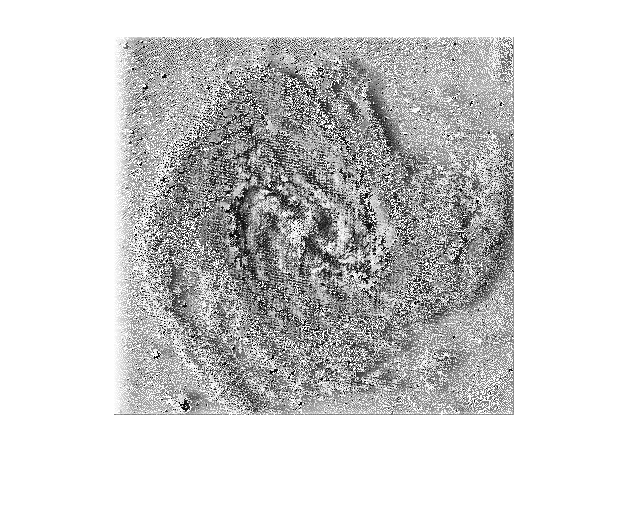

Img=A;
     
  
%WINDOW SIZE
M=10;
N=20;


mid_val=round((M*N)/2);

%FIND THE NUMBER OF ROWS AND COLUMNS TO BE PADDED WITH ZERO
in=0;
for i=1:M
    for j=1:N
        in=in+1;
        if(in==mid_val)
            PadM=i-1;
            PadN=j-1;
            break;
        end
    end
end
%PADDING THE IMAGE WITH ZERO ON ALL SIDES
B=padarray(A,[PadM,PadN]);

for i= 1:size(B,1)-((PadM*2)+1)
    
    for j=1:size(B,2)-((PadN*2)+1)
        cdf=zeros(256,1);
        inc=1;
        for x=1:M
            for y=1:N
  %FIND THE MIDDLE ELEMENT IN THE WINDOW          
                if(inc==mid_val)
                    ele=B(i+x-1,j+y-1)+1;
                end
                    pos=B(i+x-1,j+y-1)+1;
                    cdf(pos)=cdf(pos)+1;
                   inc=inc+1;
            end
        end
                      
        %COMPUTE THE CDF FOR THE VALUES IN THE WINDOW
        for l=2:256
            cdf(l)=cdf(l)+cdf(l-1);
        end
            Img(i,j)=round(cdf(ele)/(M*N)*255);
     end
end
figure,imshow(Img);

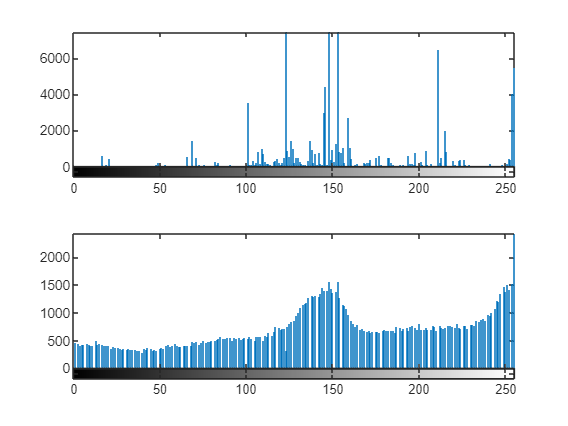

figure,
subplot(2,1,1);title('Before Local Histogram Equalization'); imhist(A);
subplot(2,1,2);title('After Local Histogram Equalization'); imhist(Img);